# Chapter 3

*Original author: Allen Downey (2017)*

*Author: Zachary del Rosario (2020)*

% Set the random state
rng(101)

% NOTE: If this cell is successful, it produces no output

## From Last Time

A solution to the last exercise in the Chapter 2 notebook would look like the following:

% NOTE: This is defined in `fcn_simulate.m`
% (1) Function signature
% function tab_record = fcn_simulate(tab_state, p_o2w, p_w2o, num_steps)
% (2) Documentation
% % simulate_bikeshare Run a bikeshare simulation
% %
% % Usage
% %   state = simulate_bikeshare(state, p_o2w, p_w2o, num_steps)
% %
% % Arguments
% %   state = bikeshare state
% %   p_o2w = probability of bicycle going from Olin to Wellesley
% %   p_w2o = probability of bicycle going from Wellesley to Olin
% %   num_steps = number of steps to simulate
% %
% % Examples
% %   % Create an initial state
% %   tab_state = fcn_make_table("olin", 10, "wellesley", 3);
% %   % Simulate 60 steps with p_o2w = 0.3, p_w2o = 0.2
% %   tab_record = fcn_simulate(tab_state, 0.3, 0.2, 60);
% 
% (3) Function body
% % Copy the state
% tab_record = tab_state;
% 
% for i = 1 : num_steps
%     tab_state = step(tab_state, p_o2w, p_w2o);
%     tab_record = [tab_record; tab_state];
% end
% 
% end

Let's step through the pieces of this function:

- **Function signature:** This is the "business end" of the function where we define its outputs (`tab_record`), its name (`fcn_simulate), and its inputs (tab_state, etc.)`

- **Documentation:** This is the "human readable" part of the function; most function documentation tells us what the function does (at a high level), and some information about its inputs and outputs. Ideally, documentation should also include *examples* of how the code is intended to be used---this helps you understand what kinds of problems the function was designed to solve. When you write your own function, you are responsible for writing your own documentation!

- **Function body:** This is the "computer readable" part of the function; this code *implements* the ideas we expressed in human language.

With this kind of function we can easily run multiple simulations from *different starting conditions*. But first, let's fix that pesky negative bike problem.

## Negative Bikes

We could fix the negative bike problem with a *conditional*; for instance, if there were zero bikes at Olin, we could simply "hit the breaks" by using the `return` keyword:

% NOTE: This is an example function
% function state = fcn_olin2wellesley(state)
% 
% if state.olin == 0
%     return
% end
% 
% state.olin = state.olin - 1;
% state.wellesley = state.wellesley + 1;
% 
% end

The `return` keyword "stops the function early"; if the condition `state.olin == 0` is met, then `return` tells the function to halt before it starts modifying the bike counts. Execution starts at the top of the function and proceeds until the end, or until we tell it to stop with `return`.

This is a good time to take a detour about a common programming problem:

## Comparison operators

The `if` statements in the previous section used the comparison operator `==`.  The other comparison operators are listed in the book.

It is easy to confuse the comparison operator `==` with the assignment operator `=`.

Remember that `=` creates a variable or gives an existing variable a new value.

x = 5

x = 5

Whereas `==` compares two values and returns 1 if they are equal.

x == 5

ans = logical
   1


You can use `==` in an `if` statement.

if x == 5
    disp("x is equal to 5")
end

x is equal to 5


But if you use `=` in an `if` statement...

% TODO: Uncomment and run the following code
% if x = 5
%     disp("You're not going to see this!")
% end

`Matlab will give you the helpful message: `

`Error: Incorrect use of '=' operator. To assign a value to a variable, use '='. To compare values for equality, use '=='.`

**Exercise:** Add an `else` clause to the `if` statement above, and print an appropriate message.

Replace the `==` operator with one or two of the other comparison operators, and confirm they do what you expect.

## Metrics

Now that we have a working simulation, we'll use it to evaluate alternative designs and see how good or bad they are.  The metric we'll use is the number of customers who arrive and find no bikes available,  which might indicate a design problem.

bikeshare = fcn_make_table( ...
    "olin", 10, ...
    "wellesley", 3, ...
    "olin_empty", 0, ...
    "wellesley_empty", 0 ...
)

bikeshare = 1×4 table
    olin    wellesley    olin_empty    wellesley_empty
    ____    _________    __________    _______________

     10         3            0                0       


To take advantage of these new variables, we'll need to modify the bike update function:

% NOTE: This is defined in fcn_olin2wellesley.m`
% function tab_state = fcn_olin2wellesley(tab_state)
% 
% if tab_state.olin == 0
%     tab_state.olin_empty = tab_state.olin_empty + 1;
%     return
% end
% 
% tab_state.olin = tab_state.olin - 1;
% tab_state.wellesley = tab_state.wellesley + 1;
% 
% end

Here we've added a line to increment the `olin_empty` variable in our state

**Exercise:** First *hypothesize* what would happen if you were to exchange the lines `tab_state.olin_empty = tab_state.olin_empty + 1` and `return`. Then open the function `fcn_olin2wellesley.m` and make the change. Try running the code below with both versions, and note the differences.

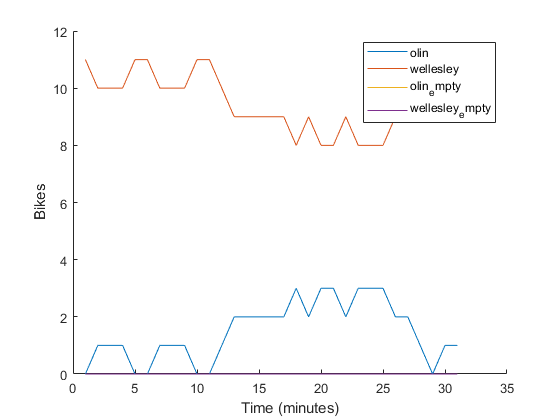

% NOTE: No need to edit this initial state
tab_bikeshare0 = fcn_make_table( ...
    "olin", 0, ...
    "wellesley", 11, ...
    "olin_empty", 0, ...
    "wellesley_empty", 0 ...
);
% TODO: Edit the file fcn_olin2wellesley.m to swap the return line; 
%       document how the results change.
tab_record0 = fcn_simulate(tab_bikeshare0, 0.5, 0.5, 30);
plt_record(tab_record0);

**Observations:**

- What happens with the original version?

- What happens when you swap the order of the lines? Why does this happen?

## More than one state object

As promised above, since we put in all this hard work *building functions*, we can find a payoff by using the same functions to *simulate different scenarios*. For instance, we can define two starting conditions:

tab_bikeshare1 = fcn_make_table( ...
    "olin", 10, ...
    "wellesley", 3, ...
    "olin_empty", 0, ...
    "wellesley_empty", 0 ...
);
tab_bikeshare2 = fcn_make_table( ...
    "olin", 2, ...
    "wellesley", 11, ...
    "olin_empty", 0, ...
    "wellesley_empty", 0 ...
);

We can simulate these two states independently.

tab_record1 = fcn_simulate(tab_bikeshare1, 0.3, 0.2, 30);
tab_record2 = fcn_simulate(tab_bikeshare2, 0.3, 0.2, 30);

And then use a helper function plot the records.

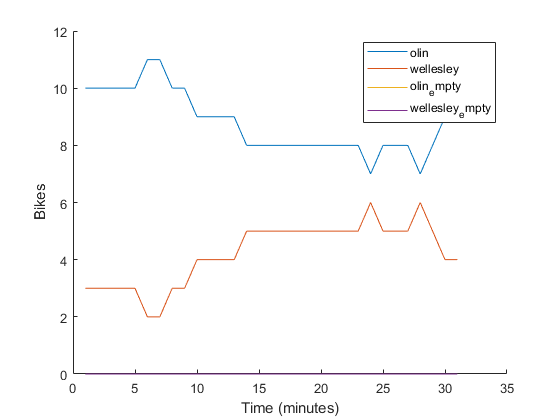

plt_record(tab_record1);

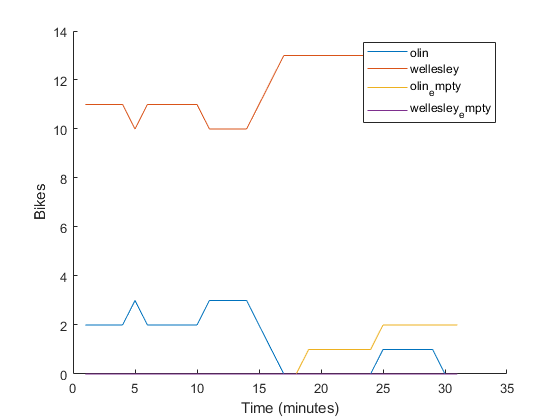

plt_record(tab_record2);

Now in the second simulation results `tab_record2` we can see that a handful of customers didn't manage to find a bike at Olin and gave up. This metric is an important indicator of a potential problem---studying these metrics could help us decide how to rebalance the bikeshare system.